# Exam January 11, 2018

## Exercise 1

%Panda robot
clear ; close all
q = sym('q',[1 7])

$$q = \left(\begin{array}{ccccccc} q_{1} & q_{2} & q_{3} & q_{4} & q_{5} & q_{6} & q_{7} \end{array}\right)$$

al = pi/2; % rotation 
%a = 3
%d = 10
syms a d 
dh = [al 0 d q(1);
      -al 0 0 q(2);
      al a d q(3);
      -al -a 0 q(4);
      al 0 d q(5);
      al a 0 q(6);
        0 0 d q(7);]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & d & q_{1}\\ -\frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & a & d & q_{3}\\ -\frac{\pi }{2} & -a & 0 & q_{4}\\ \frac{\pi }{2} & 0 & d & q_{5}\\ \frac{\pi }{2} & a & 0 & q_{6}\\ 0 & 0 & d & q_{7} \end{array}\right)$$




[T1 Tpartial] = getTranslationMatrix(dh,'alpha')

Tpartial = 1×7 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


[T2 Tpartial2] = getTranslationMatrix(dh.*[-ones(7,1) ones(7,3)],'alpha')

Tpartial2 = 1×7 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


dh = subs(dh,[a d],[10 100])    

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 100 & q_{1}\\ -\frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & 10 & 100 & q_{3}\\ -\frac{\pi }{2} & -10 & 0 & q_{4}\\ \frac{\pi }{2} & 0 & 100 & q_{5}\\ \frac{\pi }{2} & 10 & 0 & q_{6}\\ 0 & 0 & 100 & q_{7} \end{array}\right)$$

%dh = subs(dh,[a d],[10 100])


T1-T2


dht = getDHforTB(dh,'alpha')

n = 7

dht =          0  100.0000         0    1.5708
         0         0         0   -1.5708
         0  100.0000   10.0000    1.5708
         0         0  -10.0000   -1.5708
         0  100.0000         0    1.5708
         0         0   10.0000    1.5708
         0  100.0000         0         0



r = SerialLink(dht)

 
r = 
 
noname:: 7 axis, RRRRRRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        100|          0|     1.5708|          0|
|  2|         q2|          0|          0|    -1.5708|          0|
|  3|         q3|        100|         10|     1.5708|          0|
|  4|         q4|          0|        -10|    -1.5708|          0|
|  5|         q5|        100|          0|     1.5708|          0|
|  6|         q6|          0|         10|     1.5708|          0|
|  7|         q7|        100|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


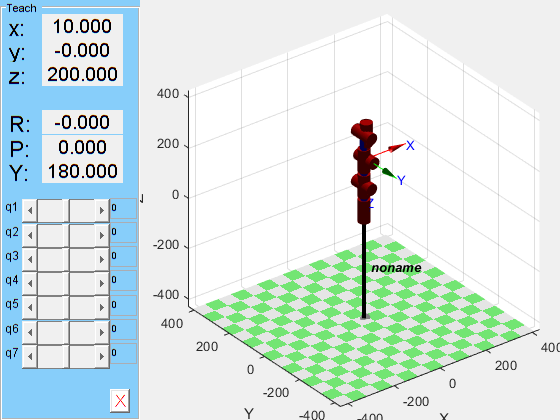

r.teach